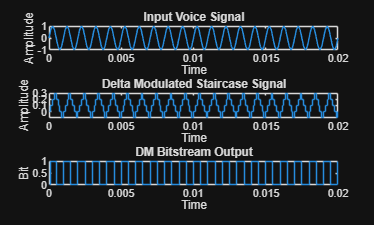

clc;
clear;
close all;

fs = 8000;              % Sampling frequency
t = 0:1/fs:0.02;        % Time vector
f = 1000;               % Voice-like frequency

x = sin(2*pi*f*t);      % Input voice signal

delta = 0.1;            % Step size
xn = zeros(size(x));    % Reconstructed signal
bitstream = zeros(size(x));

for n = 2:length(x)

    if x(n) > xn(n-1)
        bitstream(n) = 1;
        xn(n) = xn(n-1) + delta;
    else
        bitstream(n) = 0;
        xn(n) = xn(n-1) - delta;
    end

end

figure

subplot(3,1,1)
plot(t,x)
title('Input Voice Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(3,1,2)
stairs(t,xn)
title('Delta Modulated Staircase Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(3,1,3)
stairs(t,bitstream)
title('DM Bitstream Output')
xlabel('Time')
ylabel('Bit')